clear
load('/Users/danicaroth/Google Drive/Academic/Analysis/Nonlocal/TopographicData/rasters.mat')
load('/Users/danicaroth/Google Drive/Academic/Analysis/Nonlocal/RockDropData/HPB.results.mat', 'HPB_results')
load('/Users/danicaroth/Google Drive/Academic/Analysis/Nonlocal/RockDropData/Noble.results.mat', 'Noble_results')
load('/Users/danicaroth/Documents/Academic/Analysis/Nonlocal/RockDropData/final_XR.mat','Xfinal','Rfinal','CensorPoint');
iorder=[2 4 6 1 3 5 7]; %reorder X, R, Censorpoint from figure order from plot_rockdst_disentrainmentrate_FINAL.m
Xfinal=Xfinal(iorder,:); %final X values = x(x< CensorPoints) - theta(left truncation point)
Rfinal=Rfinal(iorder,:); %" above but for R
CensorPoint=CensorPoint(iorder,:); %final censor points used for each site and rock size, based on both slope breaks and tail data that overly biases lomax fit (e.g., due to collection of clasts at roots)
itheta=[repmat(.1,1,5) 0 .1]; %theta (left truncation) at all sites = 0.1, but N24 starting line data was actually ~0.1m up from point cloud start
Noble_results = Noble_results([1 2 4 5],:);
results = [HPB_results;Noble_results];
name = {'original' 'low-pass' 'high-pass'};
colors=[237 177 32; 179 177 32; 119 172 48; 119 172 48; 77 190 238; 0 131 205; 126 47 142]./255;
markersize=[1.7 4.5 7.2].^1.3;
fc=[     0    0.4470    0.7410; 0.8500    0.3250    0.0980; 0.9290    0.6940    0.1250];%colors for histograms  
tr=[300;...%transect number (manually selected for each site)
    150;...
    120;...
    94;... 55
    220;...
    155;...
    304];
i = 7;
raster={Nraster{i}' Nraster_lp{i}' Nraster_hp{i}'};
Site = N.site{i}(1:3) %print site name

Site = 'N39'

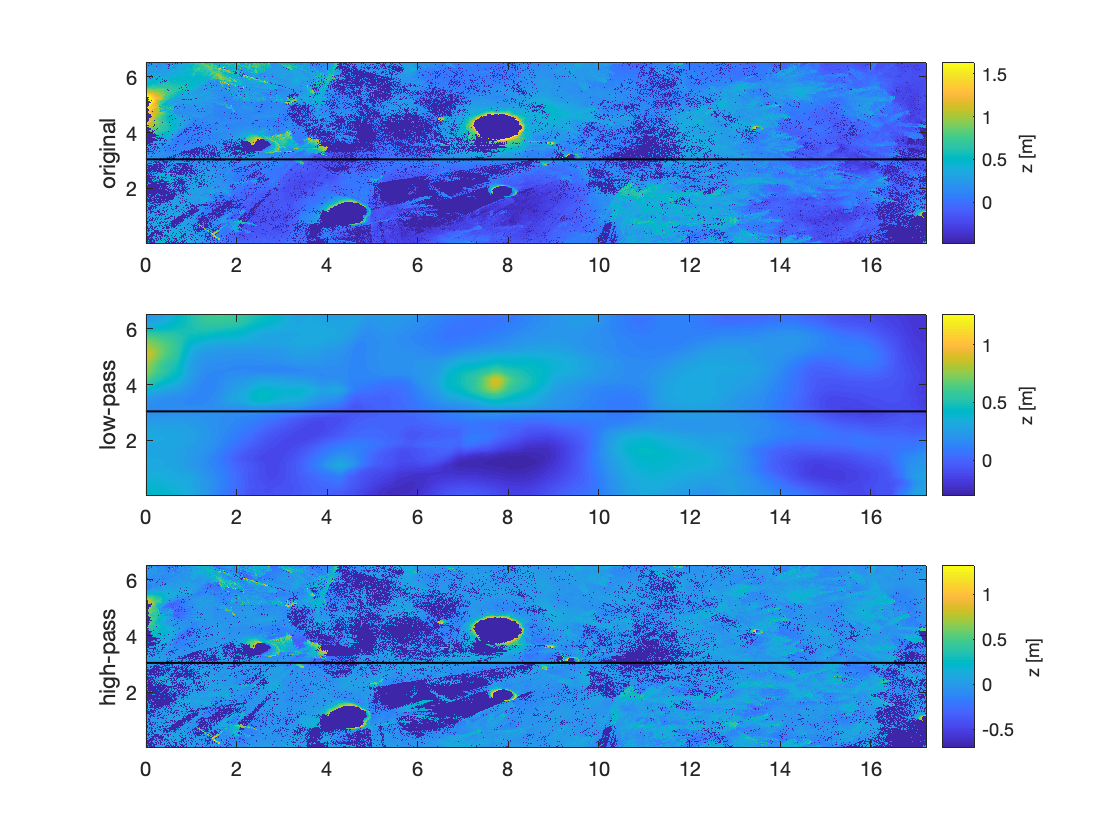

nx=size(raster{1},2); ny=size(raster{1},1);
x = ([1:nx]./100);
yt = tr(i); %use selected transect y-values
z = raster{1}(yt,:);
zs = z-(N.slope(i).*x); %re-trend elevations in horizontal reference frame
%     z0=zs(iz(i));
x = x./cosd(N.slopedeg(i))-itheta(i); %convert x to along-ground reference frame (matching travel distances) and shift by truncation distance (theta)
y = [1:ny]./100; 
z0 = interp1(x(~isnan(zs)),zs(~isnan(zs)),0,'linear','extrap'); %extrapolate linearly to find z(x=0) to rezero z
zs = zs-z0; %rezero z to starting line (+theta) elevation

for a=1:3
    cp(a)=CensorPoint{i,a}-.1; %make i-specific cp for easy reference later
end


% Plot surface topography
figure; clf
for f=1:3
    subplot(3,1,f);
    imagesc(x,y,raster{f});
    axis xy;
    set(gca,'xlim',[0 1.05*max(cp)],'ylim',[y(1) y(end)]);
    c(f) = colorbar;
    ylabel(name{f})    
    %Plot a line showing the selected transect 
    hold on
    plot([x(1) x(end)], [y(yt) y(yt)],'k','linewidth',1);
    %Add colorbar axis labels to all subplots and label without exponent notationmatlab: opentoline('/Applications/MATLAB_R2018b.app/toolbox/matlab/graph3d/xlim.m',31,0)
    c(f).Ruler.Exponent = 0;
    set(get(c(f),'label'),'string','z [m]','Rotation',90);
end
xticklabels('auto');

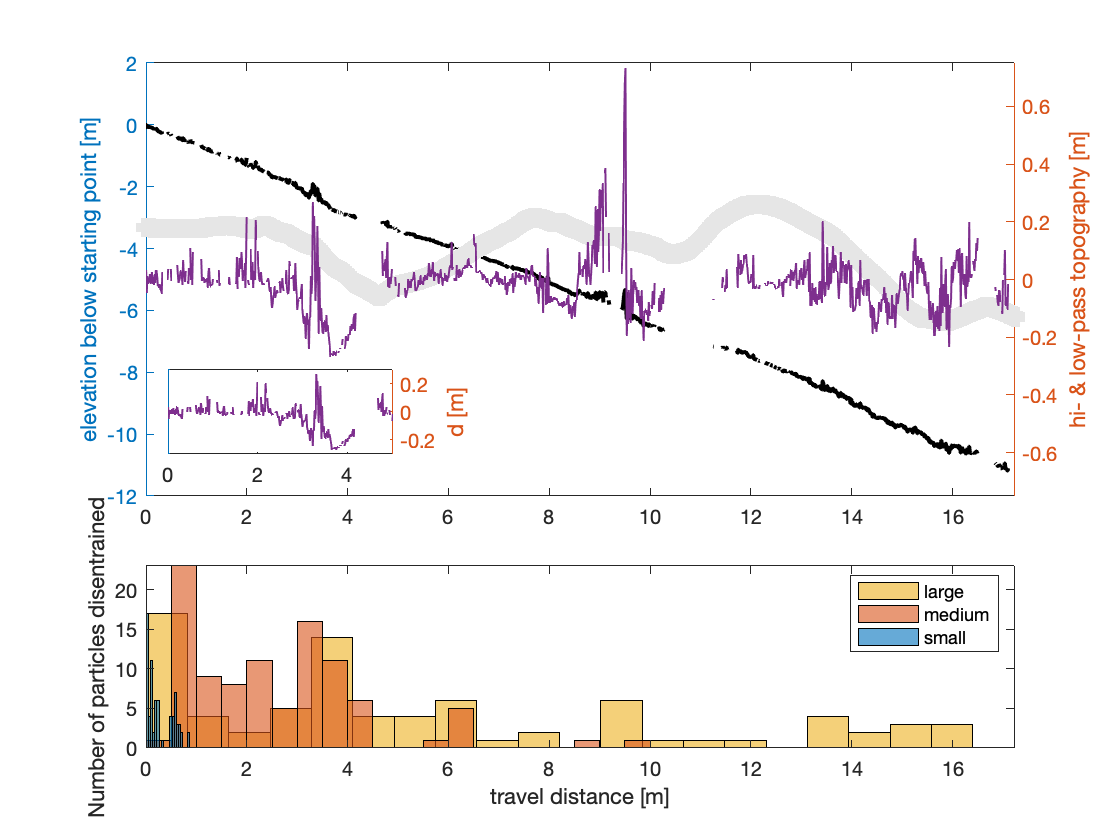


figure
clf
%Plot the topographic transects 
subplot(3,1,1:2)
yyaxis left
plot(x,zs,'k','linewidth',[2]); hold on
ylabel('elevation below starting point [m]')
yyaxis right
plot(x,raster{2}(yt,:),'-s','linewidth',5,'Color',.9*[1 1 1]);
plot(x,raster{3}(yt,:),'linewidth',[1],'Color',colors(i,:));
ylabel('hi- & low-pass topography [m]')
ylim([-.75 .75])
xlim([0 1.05*max(cp)]) %match axes with final figure 2 (x vs R)
%         hold on
%         plot(x,raster{1}(yt(i),:),'k','linewidth',1,'LineStyle','-');
%         plot(x,raster{3}(yt(i),:),'linewidth',1,'Color',colors(i,:),'LineStyle','-.');


%Plot close-up inset
axes('Position',[.15 .46 .2 .1])
box on
yyaxis left
set(gca,'YTickLabel',[]);
yyaxis right
plot(x,raster{3}(yt,:),'linewidth',[1],'Color',colors(i,:));
ylabel('d [m]')
ylim([-.3 .3])
xlim([0 5])

%Plot histograms of travel distances
subplot(3,1,3)
for r=[3 2 1]
    xdata{r} = results{i,r}.data.x(results{i,r}.data.x>0.1)-0.1;
    xdata{r} = xdata{r}(xdata{r}<CensorPoint{i,r});
    histogram(xdata{r},20,'FaceColor',fc(r,:)); hold on
end
ylabel('Number of particles disentrained')
xlabel('travel distance [m]')
legend('large','medium','small')
xlim([0 1.05*max(cp)])





% % EXAMINE RANGE OF yt VALUES IN DETAIL
% x = ([1:nx]./100)./cosd(N.slopedeg(i))-0.1;
% y = [1:ny]./100; 
% 
% figure(50)
% ytest=91:93; % numbers for i = 5 = 220:230
% clf
% yyaxis right
% for r=[3 2 1]
%     xdata{r} = results{i,r}.data.x(results{i,r}.data.x>0.1)-0.1;
%     xdata{r} = xdata{r}(xdata{r}<CensorPoint{i,r});
%     histogram(xdata{r},20,'FaceColor',fc(r,:)); hold on
% end
% yyaxis left
% legtext={};
% for yt=ytest
% %     % Uncomment for z
% %     z = raster{1}(yt,:);
% %     zs = z-(N.slope(i).*x);
% %     for a=1:3
% %         cp(a)=CensorPoint{i,a};
% %     end
% %     plot(x,zs+(yt-ytest(1)).*.1,'linewidth',[1]); hold on
% %     ylabel('elevation above censor point [m]')
% %     xlim([0 1.05*max(cp)])
% 
%     % Uncomment for hi-pass
% %     plot(x,raster{3}(yt,:)+(yt-ytest(1)).*.1,'linewidth',[1]); hold on
%     plot(x,raster{3}(yt,:)-nanmean(raster{3}(yt,:)),'linewidth',[1]); hold on
%     ylabel('d [m]')
%     xlim([0 5])
% 
% legtext=[legtext (num2str(yt))];
% end
% legend(legtext);

